# Autoencoder -based anomaly detection for pump data 

`Copyright 2019-2020 The MathWorks, Inc.`

This demo highlights how one can use a semi-supervised machine learning technique based on autoencoder to detect an anomaly in sensor data (output pressure of a triplex pump). The demo also shows how a trained autoencoder can be deployed on an embedded system through automatic code generation. The advantage of autoencoders is that they can be trained to detect anomalies with data representing normal operation, i.e. you don't need data from failures.

## Autoencoder basics

Autoencoders are based on neural networks, and the network consists of two parts: an encoder and a decoder. Encoder compresses the N-dimensional input (e.g. a frame of sensor data) into an x-dimensional code (where x < N), which contains most of the information carried in the input, but with fewer data. Hence, the encoder is somewhat similar to *principal component analysis*, but autoencoders can capture non-linear relationships. The decoder, on the other hand, tries to regenerate the input from the lower-dimensional *code *or *latent representation.* 

The way one can use trained autoencoders for anomaly detection is that in normal conditions, when normal data is fed into the network, the network can regenerate the input, and the error between the input and output is small. When data containing anomalies is fed into the network, the network fails to regenerate the input, and the error becomes larger.

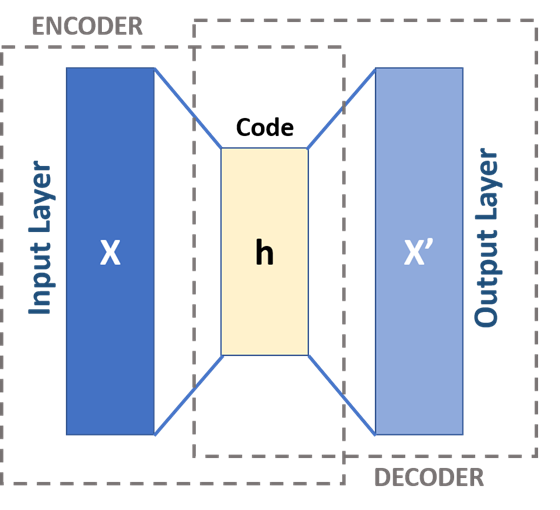

## Load data

Here we will just load two snapshots of data, the other one is data that represents normal operation, and the other one has an anomaly.

NOTE: only normal data is needed to train the anomaly detector

clear
load autoencoder_data.mat

## Visualize data

Let's visualize the normal data, and the data containing anomalies. We see that the anomalies are not clearly visible, but on a closer inspection, we see that the regular pattern is broken at around 1350 samples.

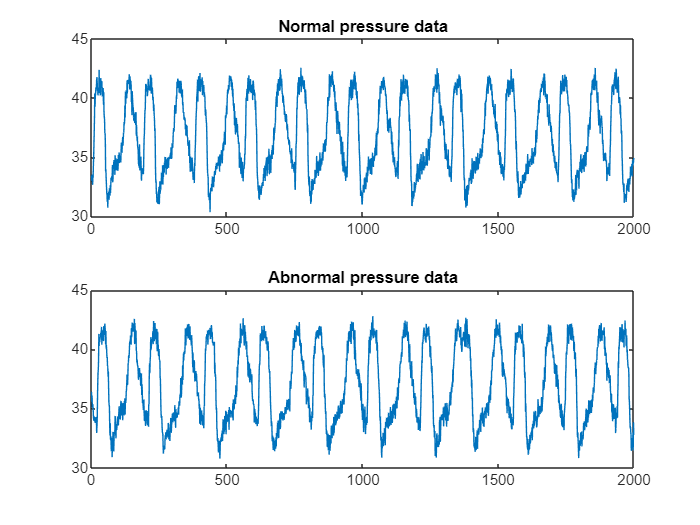

tiledlayout('flow')
nexttile,plot(normaldata(1:2000)), title('Normal pressure data')
nexttile,plot(faultydata(1:2000)), title('Abnormal pressure data')

## Reorganize data into a matrix of frames

Here we organize the data into overlapping frames (one sample difference).

w = 100; % Length of frame
traindata_ae = generateSubseq(normaldata, w)';
testdata_ae = generateSubseq(faultydata, w)';

## Setup Autoencoder options

These options define the autoencoder and training properties. Here we use 30 hidden nodes, which means that we're representing the input (100 samples) with 30 weights.

option.MaxEpochs = 500;
option.hiddenSize = 30; % number of hidden nodes, i.e. the dimension of the "code"
option.L2WeightRegularization = 1.0e-10;
option.SparsityRegularization = 1.0e-10;
option.SparsityProportion = 0.7;
option.ScaleData = true;
option.UseGPU = false;

## Train the Autoencoder model

autoenc = trainAutoencoder(traindata_ae, option.hiddenSize, ...
    'MaxEpochs', option.MaxEpochs, ...
    'L2WeightRegularization', option.L2WeightRegularization, ...
    'SparsityRegularization', option.SparsityRegularization, ...
    'SparsityProportion', option.SparsityProportion, ...
    'ScaleData', option.ScaleData, ...
    'UseGPU', option.UseGPU);

## Do the encode-decode

Let's take one frame of data and feed it into the trained network. Let's then visualize the input, the code, the output and the error between input and output. We see that the trained network can reproduce the input pattern and noise is removed (autoencoders can also be used for denoising!)

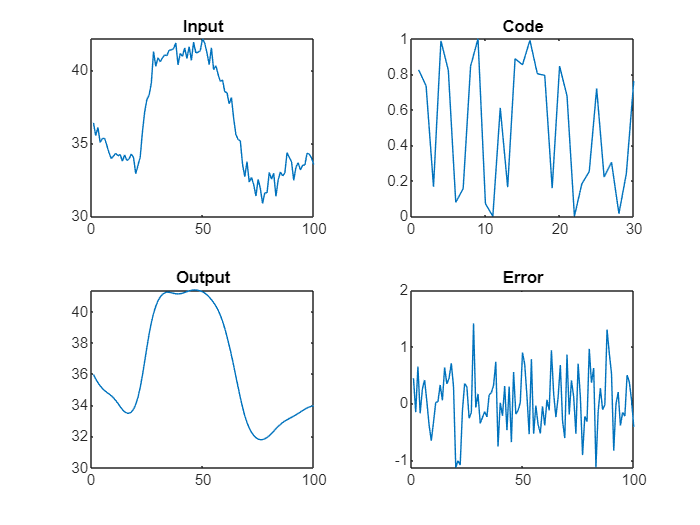

code = encode(autoenc,testdata_ae(:,1));
decoded = decode(autoenc,code);

tiledlayout('flow')
nexttile
plot(testdata_ae(:,1)),title('Input')
nexttile
plot(code),title('Code')
nexttile
plot(decoded),title('Output')
nexttile
plot(testdata_ae(:,1)-decoded), title('Error')

## Calculate the error for the entire test set and visualize

Let's now test with the entire dataset and see if our network can spot the anomaly. And indeed wee see that it can.

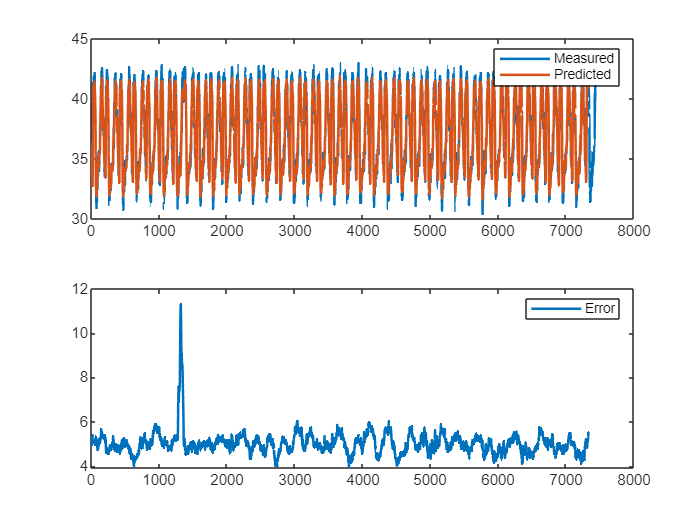

% Make a prediction with the entire test dataset
y_hat = predict(autoenc, testdata_ae);

% Calculate the error
E1 = sqrt(sum((y_hat - testdata_ae).^2));
X1_hat = y_hat(1, :);

% Plot
ax1 = subplot(2, 1, 1);
plot(1:length(faultydata), faultydata, 1:length(X1_hat), X1_hat, 'LineWidth',1.5), legend('Measured','Predicted')

ax2 = subplot(2, 1, 2);
plot(1:length(E1), E1, 'LineWidth',1.5), legend('Error')

linkaxes([ax1 ax2],'x')

## Run the detector sample by sample

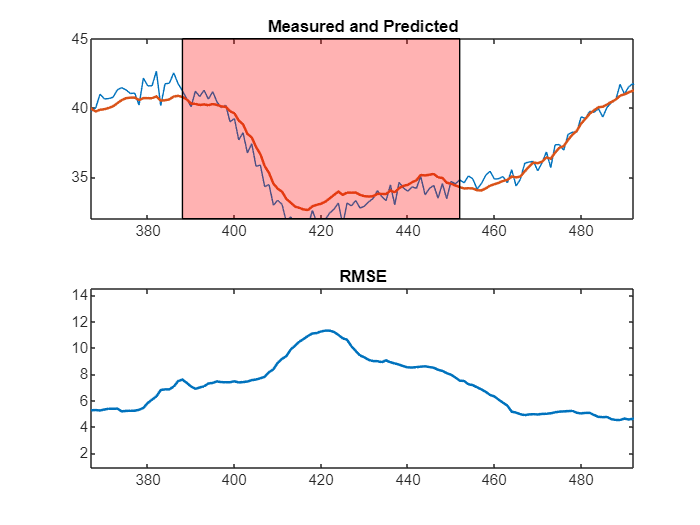

runDetection

## Create a MATLAB function from the autoencoder object

To deploy on embedded systems, we first need to convert our model into a MATLAB function. We do this with `generateFunction`

load autoEncModel.mat
generateFunction(autoenc,'anomalyDetectorFunc.m')

 
MATLAB function generated: anomalyDetectorFunc.m
To view generated function code: edit anomalyDetectorFunc
For examples of using function: help anomalyDetectorFunc
 


## Put everything together

We then put everything into a simple function that takes a data sample from sensors, accumulates data into a buffer, makes predictions with the prediction-function we generated above, and then identifies the indexes of anomalies. This function supports code generation.

% edit detectAnomalies.mlx

## Generate C code for the MATLAB code

% codegen detectAnomalies.mlx -config:lib -c -args ones(1,1) -launchreport